Mouse (Light) — Total=5300 | Kept=4005 | Dropped=1295  [LW-only=1283; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


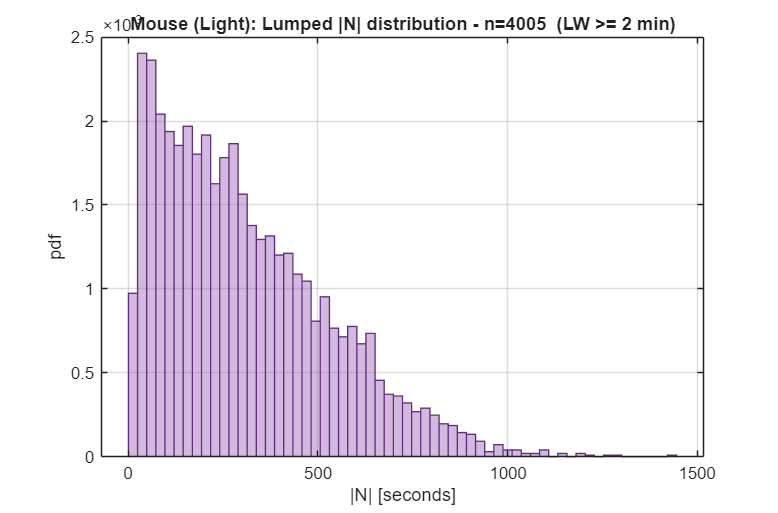

  Bin 1: REMpre in [0, 30) s | n=1764
       comp1: w=0.567662, mu=4.675470, sd=0.744509
       comp2: w=0.432338, mu=5.584741, sd=0.429150
  Bin 2: REMpre in [30, 60) s | n=955
       comp1: w=0.276038, mu=4.145471, sd=0.800555
       comp2: w=0.723962, mu=5.700470, sd=0.456541
  Bin 3: REMpre in [60, 90) s | n=538
       comp1: w=0.211785, mu=3.966484, sd=1.014220
       comp2: w=0.788215, mu=6.073782, sd=0.374488
  Bin 4: REMpre in [90, 120) s | n=359
       comp1: w=0.081033, mu=3.713749, sd=0.993510
       comp2: w=0.918967, mu=6.241688, sd=0.335745
  Bin 5: REMpre in [120, 150) s | n=214
       comp1: w=0.060911, mu=3.495562, sd=0.707380
       comp2: w=0.939089, mu=6.341849, sd=0.307428
  Bin 6: REMpre in [150, Inf) s | n=175
       comp1: w=0.060678, mu=5.990467, sd=0.585353
       comp2: w=0.939322, mu=6.501796, sd=0.254247
  Saved GMM parameter table: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light_GMMparams_by_REMp

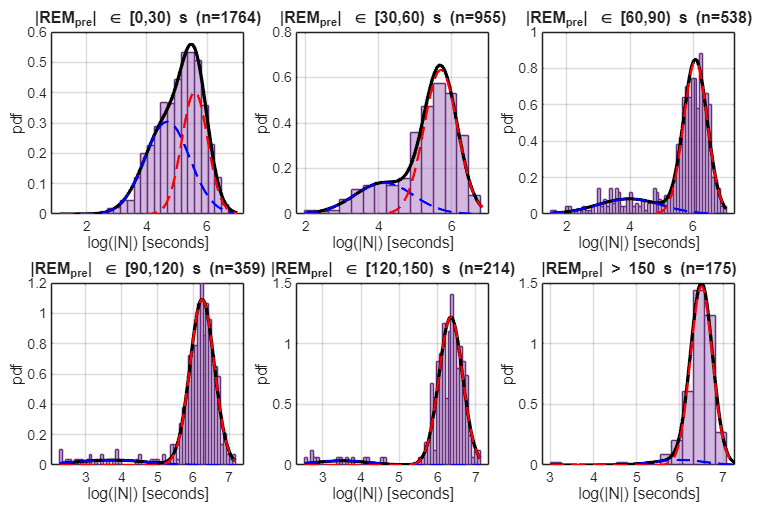

%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

clear; clc; close all;

%% ---------------- Long-wake threshold ----------------
WAKE_BREAK_MIN = 2;                  % minutes
WAKE_BREAK_SEC = WAKE_BREAK_MIN*60;  % seconds

%% ---------------- Paths ----------------
mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";

%% ---------------- Knobs ----------------
SAVE_FIGS      = false;
SHOW_WEIGHTED  = true;    % show w_k*N(mu,sd)
SHOW_SHAPES    = false;   % show normalized shapes
sdMinLog       = 0.04;
sdMaxLog       = 4.0;
nStarts        = 25;
JITTER_FRAC    = 0.25;    % ≤ 1/4 epoch de-quantization

% small-n behavior
MIN_N_FOR_GMM  = 15;
VAR_GUARD      = 2*sdMinLog;
MERGE_TAIL_IF_SMALL = true;

% Colors
mouseCol = [0.55 0.27 0.68];
ratCol   = [0.90 0.50 0.10];

%% ---------------- Species config (epoch only used for jitter size) ----------------
CFG.Mouse.epoch = 2.5;  CFG.Mouse.col = mouseCol;
CFG.Rat.epoch   = 4.0;  CFG.Rat.col   = ratCol;

%% ---------------- FIXED REMpre edges (seconds) — 6 bins -> 7 edges ----------------
REM_EDGES_SEC = [0 30 60 90 120 150 inf];

%% ---------------- Run all four datasets ----------------
run_one(mouseLightCSV, "Mouse", "Light", CFG.Mouse, REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Mouse (Dark) — Total=1307 | Kept=739 | Dropped=568  [LW-only=564; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


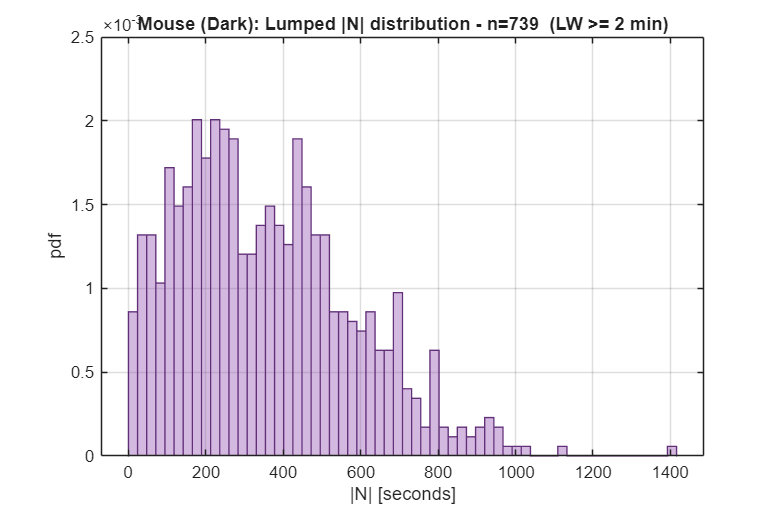

  Bin 1: REMpre in [0, 30) s | n=263
       comp1: w=0.173993, mu=4.108708, sd=0.604823
       comp2: w=0.826007, mu=5.404404, sd=0.509269
  Bin 2: REMpre in [30, 60) s | n=190
       comp1: w=0.222274, mu=4.108833, sd=1.165928
       comp2: w=0.777726, mu=5.756735, sd=0.458708
  Bin 3: REMpre in [60, 90) s | n=126
       comp1: w=0.072293, mu=3.637067, sd=0.810491
       comp2: w=0.927707, mu=6.093454, sd=0.397935
  Bin 4: REMpre in [90, 120) s | n=90
       comp1: w=0.853414, mu=6.211903, sd=0.290934
       comp2: w=0.146586, mu=6.655290, sd=0.160329
  Bin 5: REMpre in [120, 150) s | n=47
       comp1: w=0.166795, mu=5.925675, sd=0.817907
       comp2: w=0.833205, mu=6.443765, sd=0.222711
  Bin 6: REMpre in [150, Inf) s | n=23
       comp1: w=0.143032, mu=4.024097, sd=1.221474
       comp2: w=0.856968, mu=6.400669, sd=0.202421
  Saved GMM parameter table: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark_GMMparams_by_REMpreBin_

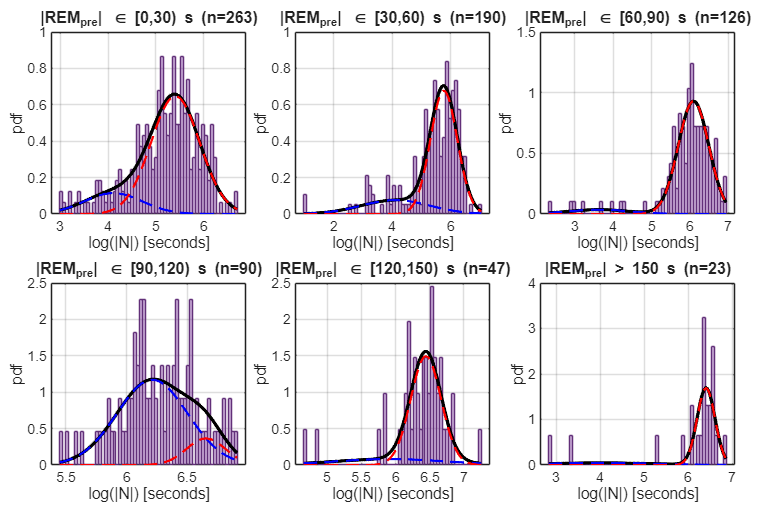


run_one(mouseDarkCSV,  "Mouse", "Dark",  CFG.Mouse, REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Rat (Light) — Total=2766 | Kept=2089 | Dropped=677  [LW-only=674; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


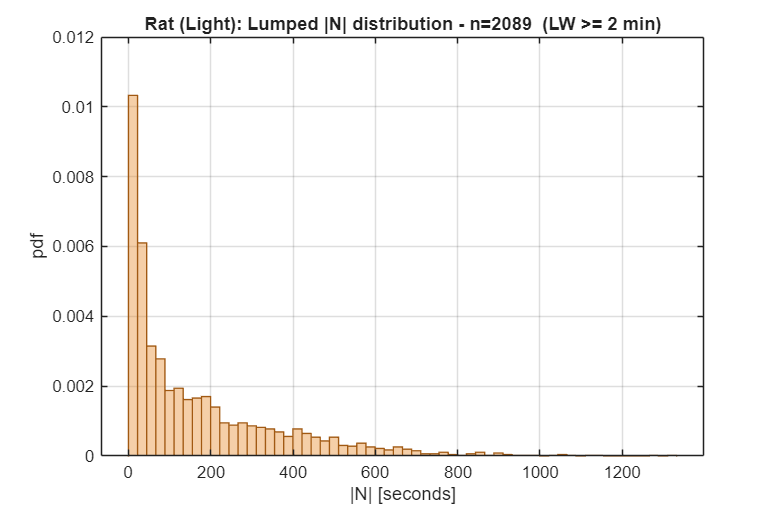

  Bin 1: REMpre in [0, 30) s | n=1218
       comp1: w=0.561366, mu=3.119637, sd=1.062033
       comp2: w=0.438634, mu=5.087218, sd=0.689585
  Bin 2: REMpre in [30, 60) s | n=217
       comp1: w=0.495110, mu=3.741384, sd=1.101963
       comp2: w=0.504890, mu=5.711540, sd=0.529854
  Bin 3: REMpre in [60, 90) s | n=152
       comp1: w=0.363205, mu=2.856820, sd=0.700839
       comp2: w=0.636795, mu=5.512436, sd=0.686096
  Bin 4: REMpre in [90, 120) s | n=129
       comp1: w=0.696851, mu=4.115882, sd=1.378561
       comp2: w=0.303149, mu=5.987688, sd=0.215465
  Bin 5: REMpre in [120, 150) s | n=171
       comp1: w=0.348737, mu=3.315828, sd=0.926647
       comp2: w=0.651263, mu=5.866690, sd=0.504538
  Bin 6: REMpre in [150, Inf) s | n=202
       comp1: w=0.324789, mu=2.923347, sd=0.802985
       comp2: w=0.675211, mu=6.014040, sd=0.494116
  Saved GMM parameter table: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light_GMMparams_by_REMpreBin_

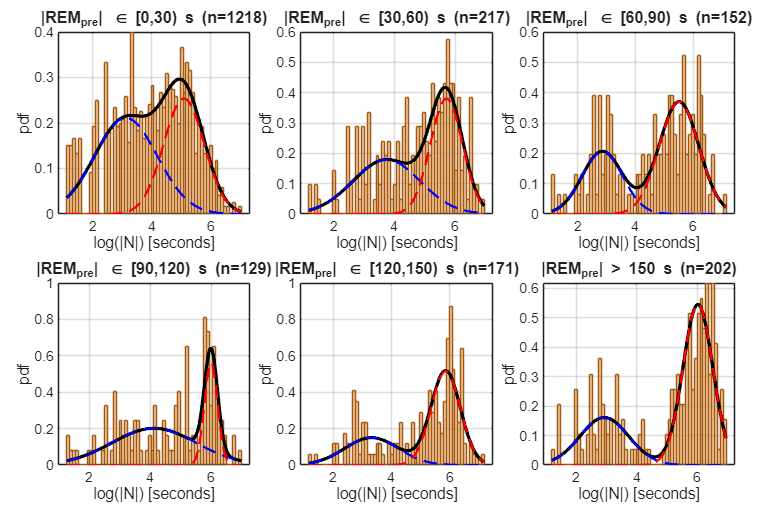


run_one(ratLightCSV,   "Rat",   "Light", CFG.Rat,   REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);

Rat (Dark) — Total=2312 | Kept=1745 | Dropped=567  [LW-only=565; Wake (total in IREM; fallback proxy) >= 120s; thr=2 min]


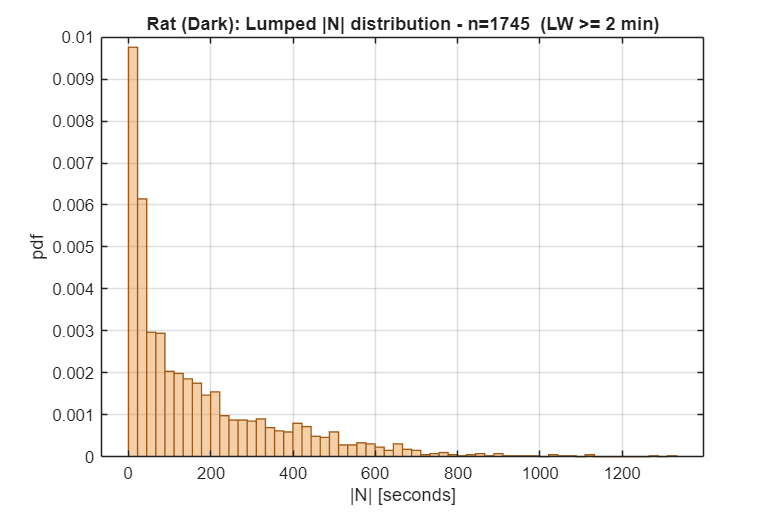

  Bin 1: REMpre in [0, 30) s | n=1012
       comp1: w=0.539199, mu=3.171425, sd=1.062828
       comp2: w=0.460801, mu=5.049042, sd=0.711461
  Bin 2: REMpre in [30, 60) s | n=162
       comp1: w=0.489062, mu=3.693498, sd=1.041146
       comp2: w=0.510938, mu=5.759963, sd=0.521715
  Bin 3: REMpre in [60, 90) s | n=140
       comp1: w=0.339023, mu=2.808336, sd=0.569335
       comp2: w=0.660977, mu=5.517960, sd=0.649666
  Bin 4: REMpre in [90, 120) s | n=115
       comp1: w=0.351201, mu=3.078538, sd=0.926275
       comp2: w=0.648799, mu=5.581982, sd=0.658780
  Bin 5: REMpre in [120, 150) s | n=147
       comp1: w=0.295944, mu=3.150063, sd=0.759568
       comp2: w=0.704056, mu=5.806371, sd=0.558362
  Bin 6: REMpre in [150, Inf) s | n=169
       comp1: w=0.321149, mu=2.972749, sd=0.745363
       comp2: w=0.678851, mu=5.986097, sd=0.504642
  Saved GMM parameter table: C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark_GMMparams_by_REMpreBin_LW

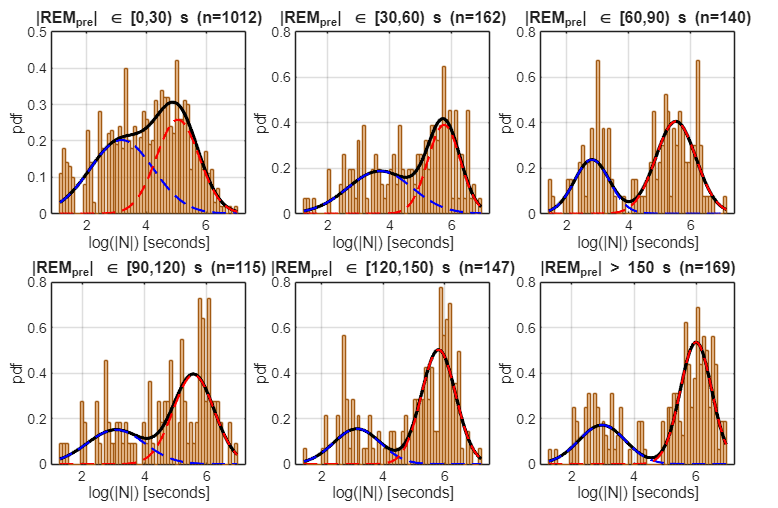


run_one(ratDarkCSV,    "Rat",   "Dark",  CFG.Rat,   REM_EDGES_SEC, ...
        SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL);


fprintf("Done.\n");

Done.



%% ================= Function =================
function run_one(csvFile, species, phase, cfg, REM_EDGES_SEC, ...
                 SAVE_FIGS, SHOW_WEIGHTED, SHOW_SHAPES, sdMinLog, sdMaxLog, nStarts, JITTER_FRAC, ...
                 WAKE_BREAK_SEC, WAKE_BREAK_MIN, MIN_N_FOR_GMM, VAR_GUARD, MERGE_TAIL_IF_SMALL)

    assert(isfile(csvFile), 'CSV not found: %s', csvFile);
    Traw = readtable(csvFile, 'TextType','string');

    % Normalize columns (guarantee Wake exists + numeric)
    T = normalize_cycles_csv(Traw);

    % Long-wake filtering (CONSISTENT with pooled-stats script)
    [dropFlagLW, filterMsg] = longwake_dropflag(T, WAKE_BREAK_SEC);

    totalAll = height(T);
    Tlw      = T(~dropFlagLW, :);
    droppedLW = nnz(dropFlagLW);

    % Validity (match GMM usage: NREM finite & >0)
    valid = isfinite(Tlw.NREM) & (Tlw.NREM > 0) & isfinite(Tlw.REMpre) & (Tlw.REMpre >= 0);
    Tuse  = Tlw(valid,:);

    kept    = height(Tuse);
    dropped = totalAll - kept;  % LW + invalid NREM/REMpre
    fprintf('%s (%s) — Total=%d | Kept=%d | Dropped=%d  [LW-only=%d; %s; thr=%g min]\n', ...
            species, phase, totalAll, kept, dropped, droppedLW, filterMsg, WAKE_BREAK_MIN);

    % Use REMpre (seconds) for *binning*; |N| = NREM seconds for fitting
    RP_sec = double(Tuse.REMpre(:));
    N_sec  = double(Tuse.NREM(:));

    if numel(N_sec) < 30
        warning('%s (%s): not enough valid cycles after filtering (n=%d).', species, phase, numel(N_sec));
        return;
    end

    % Small jitter to fight discretization "combs"
    if JITTER_FRAC > 0
        jitter = (rand(numel(N_sec),1)-0.5) * (2*JITTER_FRAC*cfg.epoch);
        N_sec  = max(N_sec + jitter, eps);
    end

    z = log(N_sec);  % ln seconds for the GMM

    % EM options (no quantiles)
    opts = struct('nStarts',nStarts,'maxIter',300,'tol',1e-6, ...
                  'trimFrac',0.0,'sdMin',sdMinLog,'sdMax',sdMaxLog);

    %% ---------------- Lumped plot (|N| only; no fit) ----------------
    xN = N_sec(isfinite(N_sec) & N_sec > 0);

    f1 = figure('Color','w','Position',[120 120 820 540], ...
        'Name', sprintf('%s (%s): Lumped |N|', species, phase));

    histogram(xN, 60, 'Normalization','pdf', ...
        'FaceColor', cfg.col, 'FaceAlpha',0.38, ...
        'EdgeColor', cfg.col*0.7, 'LineWidth',0.8);
    hold on; grid on; box on;

    xlabel('|N| [seconds]');
    ylabel('pdf');
    title(sprintf('%s (%s): Lumped |N| distribution - n=%d  (LW >= %g min)', ...
          species, phase, numel(xN), WAKE_BREAK_MIN));

    if SAVE_FIGS
        [pdir, base, ~] = fileparts(char(csvFile));
        exportgraphics(f1, fullfile(pdir, sprintf('%s_gmm_lumped_Nsec_LW%gmin.png', base, WAKE_BREAK_MIN)), 'Resolution', 220);
    end

    %% ---------------- Per-REMpre fixed bins (seconds) ----------------
    % assign each cycle to a REMpre bin
    binID = discretize(RP_sec, REM_EDGES_SEC);
    nBins = numel(REM_EDGES_SEC)-1;

    [r,c] = layout_for_bins(nBins);  
    f2 = figure('Color','w','Position',[100 100 1100 720], ...
        'Name', sprintf('%s (%s): GMM per fixed REM_{pre} bins', species, phase));
    tiledlayout(r, c, 'TileSpacing','compact','Padding','compact');

    % Table for GMM parameters by bin
    GMMTable = table();

    % loop through these bins
    for b = 1:nBins
        zb = z(binID==b);
        mergedNote = '';
        mergedFlag = false;

        if MERGE_TAIL_IF_SMALL && (numel(zb) < MIN_N_FOR_GMM) && (b == nBins)
            zb = z(binID >= b-1);   % merge last two bins
            mergedNote = ' (merged tail bins)';
            mergedFlag = true;
        end

        nexttile; hold on; grid on; box on;
        [edgesB, xxB] = scott_bins(zb);
        histogram(zb, edgesB, 'Normalization','pdf', ...
                  'FaceColor', cfg.col, 'FaceAlpha',0.38, 'EdgeColor', cfg.col*0.7);

        % default outputs for this bin
        didMixture = false;
        wB  = [NaN NaN];
        muB = [NaN NaN];
        sdB = [NaN NaN];

        % Fit GMM per bin (for enough data + enough variance)
        if numel(zb) >= MIN_N_FOR_GMM && std(zb,'omitnan') > VAR_GUARD
            try
                [wB, muB, sdB] = fit_gmm_1d_noquant(zb, 2, opts);

                % sort components by mean for consistent reporting
                [muB, ord] = sort(muB);
                sdB = sdB(ord);
                wB  = wB(ord);

                mixB = gmm_pdf_grid(xxB, wB, muB, sdB);
                plot(xxB, mixB, 'k-', 'LineWidth',2.0);
                if SHOW_WEIGHTED
                    plot(xxB, wB(1)*gauss_pdf(xxB,muB(1),sdB(1)), 'b--', 'LineWidth',1.4);
                    plot(xxB, wB(2)*gauss_pdf(xxB,muB(2),sdB(2)), 'r--', 'LineWidth',1.4);
                end
                didMixture = true;
            catch
                didMixture = false;
            end
        end

        % check for fallback
        if ~didMixture && numel(zb) >= 3 && std(zb,'omitnan')>0
            mu1 = mean(zb,'omitnan'); sd1 = std(zb,'omitnan');
            plot(xxB, gauss_pdf(xxB,mu1,sd1), 'k--', 'LineWidth',1.6);
        end

        % bin title label
        xlabel('log(|N|) [seconds]'); ylabel('pdf');
        lo = REM_EDGES_SEC(b); hi = REM_EDGES_SEC(b+1);
        if isinf(hi)
            ttl_edge = sprintf('|REM_{pre}| > %d s', lo);
        else
            ttl_edge = sprintf('|REM_{pre}| \\in [%d,%d) s', lo, hi);
        end
        title(sprintf('%s (n=%d)%s', ttl_edge, numel(zb), mergedNote));

        % save GMM parameters for this bin
        if isinf(hi)
            hiOut = NaN;
        else
            hiOut = hi;
        end

        newRow = table( ...
            string(species), string(phase), b, lo, hiOut, mergedFlag, numel(zb), didMixture, ...
            wB(1), muB(1), sdB(1), wB(2), muB(2), sdB(2), ...
            'VariableNames', {'Species','Phase','BinIndex','REMpreLo_sec','REMpreHi_sec', ...
                              'MergedTailBin','n','FitSucceeded','w1','mu1_logsec','sd1_logsec', ...
                              'w2','mu2_logsec','sd2_logsec'} );
        GMMTable = [GMMTable; newRow];

        % print to command window
        fprintf('  Bin %d: ', b);
        if isinf(hi)
            fprintf('REMpre in [%g, Inf)', lo);
        else
            fprintf('REMpre in [%g, %g)', lo, hi);
        end
        fprintf(' s | n=%d%s\n', numel(zb), mergedNote);

        if didMixture
            fprintf('       comp1: w=%.6f, mu=%.6f, sd=%.6f\n', wB(1), muB(1), sdB(1));
            fprintf('       comp2: w=%.6f, mu=%.6f, sd=%.6f\n', wB(2), muB(2), sdB(2));
        else
            fprintf('       GMM not fit (insufficient n/variance or fit failed)\n');
        end
    end

    % save per bin figure
    if SAVE_FIGS
        [pdir, base, ~] = fileparts(char(csvFile));
        exportgraphics(f2, fullfile(pdir, sprintf('%s_gmm_bins_fixed_lnsec_LW%gmin.png', base, WAKE_BREAK_MIN)), 'Resolution', 220);
    end

    % save GMM parameter table
    [pdir, base, ~] = fileparts(char(csvFile));
    outCSV = fullfile(pdir, sprintf('%s_GMMparams_by_REMpreBin_LW%gmin.csv', base, WAKE_BREAK_MIN));
    writetable(GMMTable, outCSV);
    fprintf('  Saved GMM parameter table: %s\n', outCSV);
end

%% ================= Functions =================
function T = normalize_cycles_csv(T)
    need = ["REMpre","NREM","IREM","Wake","Movement"];
    vn = string(T.Properties.VariableNames);

    for v = need
        if ~ismember(v, vn)
            T.(v) = NaN(height(T),1);
        end
        T.(v) = double(T.(v));
    end

    if (~ismember("IREM", vn)) || all(isnan(T.IREM))
        if all(ismember(["NREM","Wake","Movement"], string(T.Properties.VariableNames)))
            T.IREM = double(T.NREM) + double(T.Wake) + double(T.Movement);
        end
    end
end

function [dropFlag, msg] = longwake_dropflag(T, WAKE_BREAK_SEC)
    vn = string(T.Properties.VariableNames);

    maxWakeCandidates = ["MaxWakeSec","MaxWake_s","MaxWakeInIREMSec","MaxWakeInIREM_s", ...
                         "MaxWakeBlockSec","MaxWakeBlock_s"];

    idx = find(ismember(maxWakeCandidates, vn), 1);
    if ~isempty(idx)
        cname = maxWakeCandidates(idx);
        maxWakeSec = double(T.(cname));
        dropFlag = isfinite(maxWakeSec) & (maxWakeSec >= WAKE_BREAK_SEC);
        msg = sprintf("max Wake block via %s >= %gs", cname, WAKE_BREAK_SEC);
        return;
    end

    if ismember("Wake", vn)
        w = double(T.Wake);
        dropFlag = isfinite(w) & (w >= WAKE_BREAK_SEC);
        msg = sprintf("Wake (total in IREM; fallback proxy) >= %gs", WAKE_BREAK_SEC);
        return;
    end

    dropFlag = false(height(T),1);
    msg = "NO long-wake column found (no MaxWake*/Wake) - no filtering applied";
end

function [edges, xx] = scott_bins(z)
    z = z(:); z = z(isfinite(z));
    n = numel(z);
    if n < 2 || std(z)==0
        edges = linspace(min(z), max(z), 15);
        xx = linspace(min(z), max(z), 400);
        return;
    end
    bw = 3.5*std(z) / max(n^(1/3), eps);
    zmin = min(z); zmax = max(z);
    if ~isfinite(bw) || bw<=0
        nb = 60; edges = linspace(zmin, zmax, nb+1);
    else
        edges = zmin:bw:zmax;
        if numel(edges) < 15, edges = linspace(zmin, zmax, 60+1); end
    end
    xx = linspace(zmin, zmax, 400);
end

function [w, mu, sd, info] = fit_gmm_1d_noquant(x, K, opts)
    x = x(:); x = x(isfinite(x));
    g = @(f,d) (isfield(opts,f)&&~isempty(opts.(f))) * opts.(f) + (~isfield(opts,f)||isempty(opts.(f))) * d;
    nStarts  = g('nStarts',20); maxIter = g('maxIter',300); tol = g('tol',1e-6);
    trimFrac = g('trimFrac',0.0); sdMin = g('sdMin',0.04); sdMax = g('sdMax',4.0);

    muX = mean(x); sdX = std(x);
    if isfinite(sdX) && sdX>0
        lo = muX - 6*sdX; hi = muX + 6*sdX;
        x = x(x>=lo & x<=hi);
    end
    n = numel(x);

    log2pi = log(2*pi); bestLL = -inf; best = [];
    base_mu = muX + 0.5*sdX*linspace(-1,1,K);
    base_sd = max(sdMin, 0.3*sdX)*ones(1,K);
    base_w  = ones(1,K)/K;

    for s=1:nStarts
        mu0 = base_mu + 0.10*sdX*randn(1,K);
        sd0 = max(sdMin, min(sdMax, base_sd));
        w0  = base_w;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, bestLL = LL(end); best = {w1,mu1,sd1,LL}; end
    end
    [w, mu, sd, LL] = best{:}; info = struct('loglik',LL,'n',n,'nStarts',nStarts);
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it=1:maxIter
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); P = exp(logp - m); s = sum(P,2); gamma = P ./ max(s,eps);

        if trimN>0
            [~,idx]=sort(s,'ascend'); keep=true(n,1); keep(idx(1:trimN))=false;
        else
            keep=true(n,1);
        end

        Nk = sum(gamma(keep,:),1);
        w  = Nk ./ max(sum(Nk),eps); w = max(w,1e-4); w = w/sum(w);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        xk = x(keep);
        logp = zeros(sum(keep),K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1)))
            LL = LL(1:it); break;
        end
    end
    LL = LL(1:it);
end

function y = gmm_pdf_grid(x, w, mu, sd)
    y = zeros(size(x));
    for k=1:numel(w), y = y + w(k)*gauss_pdf(x, mu(k), sd(k)); end
end

function y = gauss_pdf(x, m, s)
    y = (1./(s*sqrt(2*pi))) .* exp(-0.5*((x-m)./s).^2);
end

function L = makeLegend(showW, showS)
    L = {'data','mixture'};
    if showW, L = [L, {'comp 1 (w)','comp 2 (w)'}]; end
    if showS, L = [L, {'comp 1 (shape)','comp 2 (shape)'}]; end
end

function [r,c] = layout_for_bins(n)
    switch n
        case 1,  r=1; c=1;
        case 2,  r=1; c=2;
        case {3,4},  r=2; c=2;
        case 5,  r=2; c=3;
        case 6,  r=2; c=3;
        otherwise, c = ceil(sqrt(n)); r = ceil(n/c);
    end
end
